# Actividad 4.1 Evaluación

## Santiago Patricio Gómez Ochoa | A01735171

### Ejercicio 1

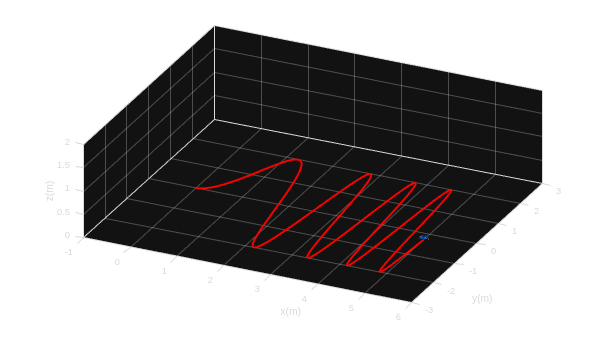

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 5;
ts = 0.001;        % paso más pequeño = menos error de Euler
t  = 0:ts:tf;
N  = length(t);

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1  = zeros(1, N+1);
y1  = zeros(1, N+1);
phi = zeros(1, N+1);

x1(1)  = 0;
y1(1)  = 0;
phi(1) = 0;        % atan(dy) en tk=0 → atan(0) = 0

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1, N+1);
hy = zeros(1, N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1, N);
w = zeros(1, N);

% Para obtener las velociades lineales y algulares, se parametriza de la forma siguiente:
% 
% x(t) = t -> dx/dt = 1
% y(t) = 2·sin(t²) -> dy/dt = 4t·cos(t²)
% Asimismo, se obtiene la segunda derivada de y para calcular la curvatura:
%       d²y/dt² = 4·cos(t²) - 8t²·sin(t²)
% 
% Utilizando estas derivadas, se obtiene la magnitud del vector velocidad tangente usando la
% siguiente expresión:
% u = sqrt( (dx/dt)² + (dy/dt)² )
% Sustituyendo:
% u = sqrt( 1 + (4t·cos(t²))² )
% 
% w indica la tasa de cambio de la orientación phi del robot, es decir,
% %   qué tan rápido gira al seguir la curvatura de la trayectoria.
% Este se calcula con la expresión:
% 
% w = d²y/dt² / (1 + (dy/dt)²)
% %         = (4·cos(t²) - 8t²·sin(t²)) / (1 + (4t·cos(t²))²)
% 
% Las velocidades u y w se usan en el modelo cinemático diferencial
% %   del robot para actualizar su posición y orientación en cada paso

for k = 1:N
    tk = t(k);

    dy  =  4 * tk * cos(tk^2);
    d2y =  4 * cos(tk^2) - 8 * tk^2 * sin(tk^2);

    u(k) = sqrt(1 + dy^2);
    w(k) = d2y / (1 + dy^2);   % fórmula correcta con dx=1, d2x=0
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k) * ts;

    x1(k+1) = x1(k) + u(k) * cos(phi(k+1)) * ts;
    y1(k+1) = y1(k) + u(k) * sin(phi(k+1)) * ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene, 'Color', 'white');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-1 6 -3 3 0 2]);

scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 5;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

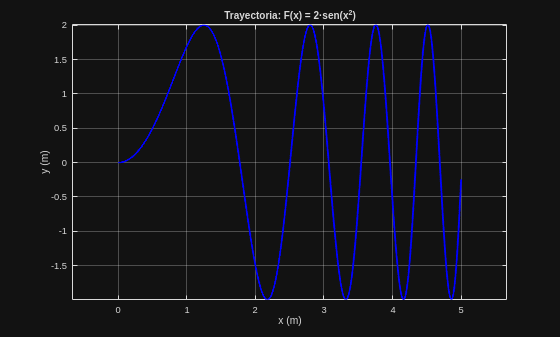


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICA TRAYECTORIA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
% x_ref = 0:0.001:5;
% y_ref = 2 * sin(x_ref.^2);
plot(hx, hy,       'b',   'LineWidth', 2);               % simulada
grid on;
xlabel('x (m)'); ylabel('y (m)');
title('Trayectoria: F(x) = 2·sen(x^2)');
axis equal;

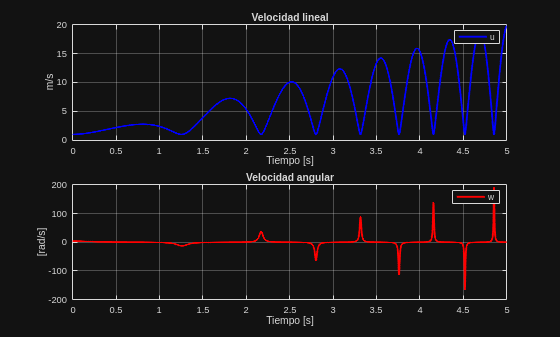


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS u y w %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
subplot(211)
plot(t, u, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')
title('Velocidad lineal')

subplot(212)
plot(t, w, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')
title('Velocidad angular')

### Ejercicio 2

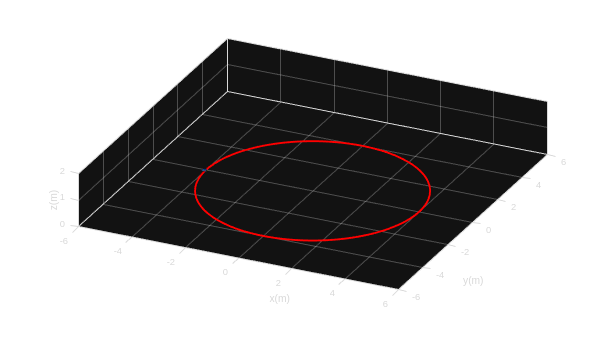

clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 2*pi;
ts = 0.01;
t  = 0:ts:tf;
N  = length(t);

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1  = zeros(1, N+1);
y1  = zeros(1, N+1);
phi = zeros(1, N+1);

% Inicio en (-4, 0) — punto rojo
x1(1)  = -4;
y1(1)  =  0;
phi(1) =  pi/2;   % apunta hacia arriba en (-4,0)

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1, N+1);
hy = zeros(1, N+1);
hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1, N);
w = zeros(1, N);

% Para obtener las velocidades lineales y angulares, se parametriza
% el círculo x² + y² = 16 de la forma siguiente:
%
% El robot parte de (-4, 0) y recorre el círculo en sentido antihorario.
% Usando la parametrización:
%   x(t) = -4·cos(t)  →  dx/dt  =  4·sin(t)
%   y(t) =  4·sin(t)  →  dy/dt  =  4·cos(t)
%
% Asimismo, se obtienen las segundas derivadas:
%   d²x/dt² =  4·cos(t)
%   d²y/dt² = -4·sin(t)
%
% Utilizando estas derivadas, se obtiene la magnitud del vector
% velocidad tangente usando la siguiente expresión:
%   u = sqrt( (dx/dt)² + (dy/dt)² )
% Sustituyendo:
%   u = sqrt( (4·sin(t))² + (4·cos(t))² ) = sqrt(16) = 4  (constante)
%
% w indica la tasa de cambio de la orientación phi del robot, es decir,
% qué tan rápido gira al seguir la curvatura de la trayectoria.
% Este se calcula con la expresión general de curvatura con signo:
%
%   w = (x'·y'' - y'·x'') / (x'² + y'²)
% Sustituyendo:
%   w = (4·sin(t)·(-4·sin(t)) - 4·cos(t)·4·cos(t)) / (16·sin²(t) + 16·cos²(t))
%     = (-16·sin²(t) - 16·cos²(t)) / 16
%     = -16/16 = -1  (constante, giro horario)
%
% Las velocidades u y w se usan en el modelo cinemático diferencial
% del robot para actualizar su posición y orientación en cada paso.

for k = 1:N
    tk = t(k);

    dxdt  =  4 * sin(tk);    % x' 
    dydt  =  4 * cos(tk);    % y' 
    d2xdt =  4 * cos(tk);    % x''
    d2ydt = -4 * sin(tk);    % y''

    u(k) = sqrt(dxdt^2 + dydt^2);                             
    w(k) = (dxdt * d2ydt - dydt * d2xdt) / (dxdt^2 + dydt^2); 
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k) * ts;

    x1(k+1) = x1(k) + u(k) * cos(phi(k+1)) * ts;
    y1(k+1) = y1(k) + u(k) * sin(phi(k+1)) * ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene, 'Color', 'white');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'position', sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-6 6 -6 6 0 2]);

scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);

step = 5;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

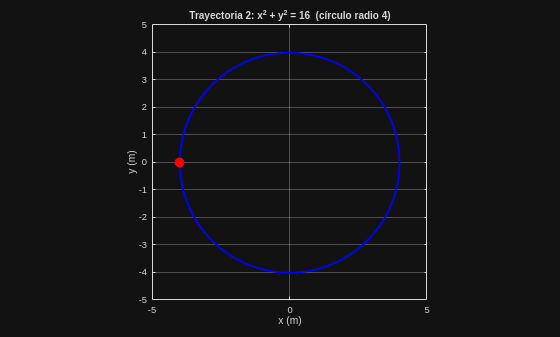


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICA TRAYECTORIA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;

% Referencia real: círculo radio 4 centrado en (0,0)
% theta_ref = linspace(0, 2*pi, 1000);
% x_ref = 4 * cos(theta_ref);
% y_ref = 4 * sin(theta_ref);
% plot(x_ref, y_ref, 'r--', 'LineWidth', 1.5); hold on;
plot(hx, hy, 'b', 'LineWidth', 2);
hold on;
plot(hx(1), hy(1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
% plot(4, 0, 'ko', 'MarkerSize', 8,  'MarkerFaceColor', 'k');

grid on;
xlabel('x (m)'); ylabel('y (m)');
title('Trayectoria 2: x^2 + y^2 = 16  (círculo radio 4)');
% legend('Referencia real', 'Simulación robot', 'Inicio (-4,0)', 'Raíz (4,0)');
axis equal;
xlim([-5 5]); ylim([-5 5]);

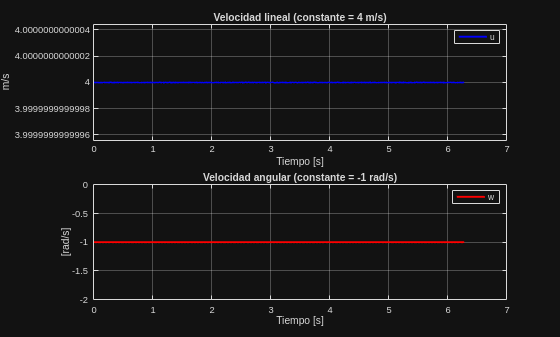


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS u y w %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
subplot(211)
plot(t, u, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')
title('Velocidad lineal')

subplot(212)
plot(t, w, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')
title('Velocidad angular')